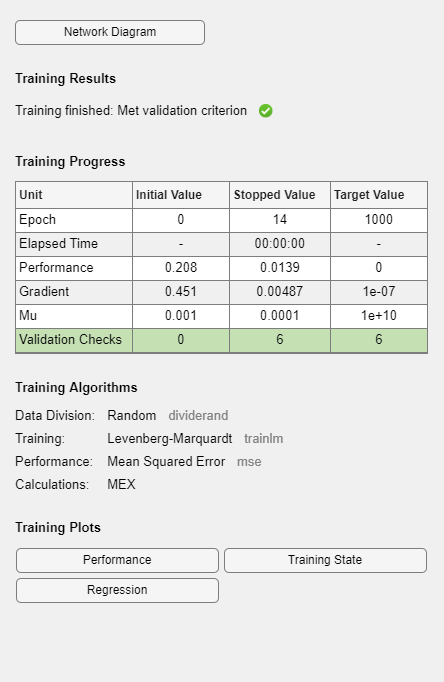

clear

M = load('StudentData/FeaturesM');
T = load('StudentData/FeaturesT');


for sample = 1:300
TrainingDataClass0(:,sample) = ...
[M.Data(sample).Normal.Area,M.Data(sample).Normal.Orientation];
TrainingDataClass1(:,sample) = ...
[T.Data(sample).Normal.Area,T.Data(sample).Normal.Orientation];
end

Means = abs(mean([TrainingDataClass0,TrainingDataClass1]'));

TrainingDataClass0 = TrainingDataClass0./Means';
TrainingDataClass1 = TrainingDataClass1./Means';



TrainingData = [TrainingDataClass0,TrainingDataClass1];
TargetTrain = [ones(1,300),zeros(1,300)];

NetworkSize = [4 4]; % Number of neurons in all the hidden layers
OurNet = newff(TrainingData,TargetTrain,NetworkSize); % Net initialization
OurNet.TrainParam.time = 10; % Max time allowed [in sec]


for reps=1:5
OurNets(reps).Net = train(OurNet,TrainingData,TargetTrain);
end

for reps=1:5
ErrorsM=0;
ErrorsT=0;
% figure;
for k = 301:600
F1 = M.Data(k).Normal.Area./Means(1)';
F2 = M.Data(k).Normal.Orientation./Means(2)';

if(sim(OurNets(reps).Net,[F1,F2]') < 0.5) % Detected class "1"
ErrorsM = ErrorsM + 1;
Res(k-300) = sim(OurNets(reps).Net,[F1,F2]');
% plot(M.Data(k).Normal.Area,M.Data(k).Normal.Orientation,'.r'); hold on
else
% plot(M.Data(k).Normal.Area,M.Data(k).Normal.Orientation,'.k'); hold on
end
F1 = T.Data(k).Normal.Area./Means(1)';
F2 = T.Data(k).Normal.Orientation./Means(2)';
if(sim(OurNets(reps).Net,[F1,F2]') >= 0.5) % Detected class "0
ErrorsT = ErrorsT + 1;
Res2(k-300) = sim(OurNets(reps).Net,[F1,F2]');
% plot(T.Data(k).Normal.Area,T.Data(k).Normal.Orientation,'+r'); hold on
else
% plot(T.Data(k).Normal.Area,T.Data(k).Normal.Orientation,'+k'); hold on
end
end
% xlabel('Area');
% ylabel('Orientation');

error(reps,1)=ErrorsT+ErrorsM;
end
disp(Res)

  Columns 1 through 12

         0         0         0         0    0.3336         0         0         0         0         0         0         0

  Columns 13 through 24

         0         0         0         0         0         0         0         0         0         0         0         0

  Columns 25 through 36

         0         0         0         0         0         0         0         0         0         0         0         0

  Columns 37 through 48

         0         0         0         0         0         0         0         0         0         0         0         0

  Columns 49 through 60

         0    0.3968         0         0         0         0         0         0         0         0         0         0

  Columns 61 through 72

         0         0         0         0         0         0         0         0         0         0         0         0

  Columns 73 through 84

         0         0         0         0         0         0         0         0         0    

error

error =     29
    22
    34
    30
    29


Task 8

4 4

2 features


for sample = 1:300
TestingDataClass1(:,sample) = ...
[M.Data(300+sample).Normal.Area,M.Data(300+sample).Normal.Orientation];
TestingDataClass0(:,sample) = ...
[T.Data(300+sample).Normal.Area,T.Data(300+sample).Normal.Orientation];
end



TestingDataClass0 = TestingDataClass0./Means'

TestingDataClass0 =     0.5048    0.2585    0.4153    0.2893    0.7711    0.2842    0.2821    0.2019    0.7711    0.2671    0.9587    0.8363    0.5026    0.3093    0.6408    0.9408    0.8721    0.2126    0.1747    0.8656    0.6336    0.6079    0.8534    0.3895    0.3988    0.4575    0.9279    0.4067    0.5728    0.2978    0.2155    0.8119    0.6215    0.6752    0.2599    0.3680    0.5706    0.3759    0.4282    0.4819    0.5878    0.4253    0.5699    0.5406    0.5470    0.4826    0.5935    0.6129    0.8699    0.4231
   -4.4839    4.5624    3.2168    4.1843    3.9896    4.4074   -4.6216   -4.6363    4.7633    4.1728    2.4089    4.7309    4.1969    4.0997   -4.5729    4.3838    4.8508   -4.6910   -4.6345    3.9051    4.3215   -4.6746    3.9401   -4.5459    3.8137    4.4277    2.7828   -4.5127    4.3240   -4.7157    4.4547   -4.8425    4.8482    4.4119   -4.6026    4.3200   -4.6585   -4.5785    4.5126   -4.6968   -4.6127    4.6479    4.4037    4.6264   -4.6594    4.4209    3.1882    4.402

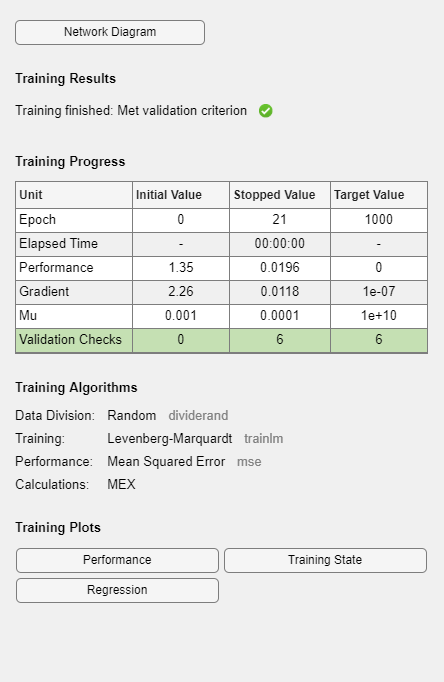

TestingDataClass1 = TestingDataClass1./Means';




NetworkSize = [4 4]; % Number of neurons in all the hidden layers
for Test = 1:5
OurNet = newff(TrainingData,TargetTrain,NetworkSize); % Net initialization
OurNet.TrainParam.time = 20; % Max time allowed
OurNet = train(OurNet,TrainingData,TargetTrain);
Results0 = sim(OurNet,TestingDataClass0);
Results1 = sim(OurNet,TestingDataClass1);
ErrorsA(Test) = sum([Results0>0.5]);
ErrorsD(Test) = sum([Results1<=0.5]);
ErrorSum(Test) = ErrorsD(Test)+ErrorsA(Test);
end

[mean(ErrorSum) std(ErrorSum)]

ans =    27.2000    3.2711


10 10 

2 features

TrainingData = [TrainingDataClass0,TrainingDataClass1];
TargetTrain = [ones(1,300),zeros(1,300)];

NetworkSize2 = [10 10]; % Number of neurons in all the hidden layers
OurNet2 = newff(TrainingData,TargetTrain,NetworkSize2); % Net initialization
OurNet2.TrainParam.time = 10; % Max time allowed [in sec]


for reps=1:5
OurNets2(reps).Net = train(OurNet2,TrainingData,TargetTrain);
Results0 = sim(OurNets2(reps).Net,TestingDataClass0);
Results1 = sim(OurNets2(reps).Net,TestingDataClass1);
ErrorsA(reps) = sum([Results0>0.5]);
ErrorsD(reps) = sum([Results1<=0.5]);
ErrorSum(reps) = ErrorsD(reps)+ErrorsA(reps);
end
[mean(ErrorSum) std(ErrorSum)]

ans =    24.4000    3.2094


4 4 4 

2 features

NetworkSize3 = [4 4 4]; % Number of neurons in all the hidden layers
OurNet3 = newff(TrainingData,TargetTrain,NetworkSize3); % Net initialization
OurNet3.TrainParam.time = 10; % Max time allowed [in sec]


for reps=1:5
OurNets3(reps).Net = train(OurNet3,TrainingData,TargetTrain);
Results0 = sim(OurNets3(reps).Net,TestingDataClass0);
Results1 = sim(OurNets3(reps).Net,TestingDataClass1);
ErrorsA(reps) = sum([Results0>0.5]);
ErrorsD(reps) = sum([Results1<=0.5]);
ErrorSum(reps) = ErrorsD(reps)+ErrorsA(reps);
end
[mean(ErrorSum) std(ErrorSum)]

ans =    25.2000    2.6833


4 f 4 4

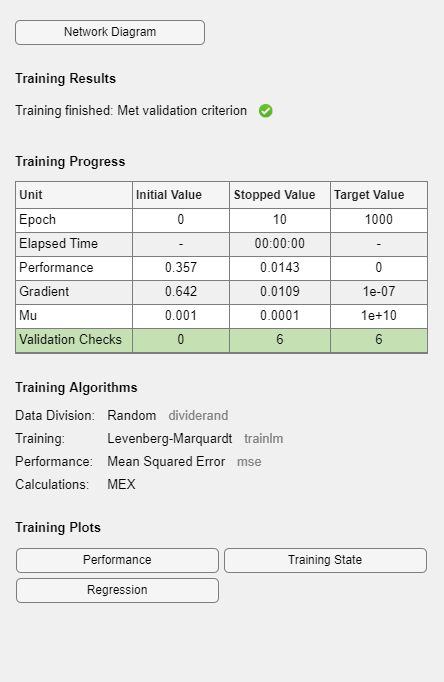

Error using network/sim
Input data sizes do not match net.inputs{1}.size.

clear TrainingDataClass0
clear TrainingDataClass1
clear TestingDataClass0
clear TestingDataClass1

for sample = 1:300
TrainingDataClass0(:,sample) = ...
[M.Data(sample).Normal.Area,M.Data(sample).Normal.Orientation,...
M.Data(sample).Normal.MajorAxisLength,M.Data(sample).Normal.MinorAxisLength];
TrainingDataClass1(:,sample) = ...
[T.Data(sample).Normal.Area,T.Data(sample).Normal.Orientation,...
T.Data(sample).Normal.MajorAxisLength,T.Data(sample).Normal.MinorAxisLength];
end

for sample = 1:300
TestingDataClass0(:,sample) = ...
[M.Data(300+sample).Normal.Area,M.Data(300+sample).Normal.Orientation,...
M.Data(300+sample).Normal.MajorAxisLength,M.Data(300+sample).Normal.MinorAxisLength];
TestingDataClass1(:,sample) = ...
[T.Data(300+sample).Normal.Area,T.Data(300+sample).Normal.Orientation,...
T.Data(300+sample).Normal.MajorAxisLength,T.Data(300+sample).Normal.MinorAxisLength];
end

Means = abs(mean([TrainingDataClass0,TrainingDataClass1]'));

TrainingDataClass0 = TrainingDataClass0./Means';
TrainingDataClass1 = TrainingDataClass1./Means';
TestingDataClass0=TestingDataClass0./Means';
TestingDataClass1=TestingDataClass1./Means';


NetworkSize3 = [4 4 4]; % Number of neurons in all the hidden layers
OurNet3 = newff(TrainingData,TargetTrain,NetworkSize3); % Net initialization
OurNet3.TrainParam.time = 10; % Max time allowed [in sec]


for reps=1:5
OurNets3(reps).Net = train(OurNet3,TrainingData,TargetTrain);
Results0 = sim(OurNets3(reps).Net,TestingDataClass0);
Results1 = sim(OurNets3(reps).Net,TestingDataClass1);
ErrorsA(reps) = sum([Results0>0.5]);
ErrorsD(reps) = sum([Results1<=0.5]);
ErrorSum(reps) = ErrorsD(reps)+ErrorsA(reps);
end

[mean(ErrorSum) std(ErrorSum)]